# Sentiment Analysis: Calling Python from MATLAB

## Set up Python and Python path

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Python39\python.EXE"
          Library: "C:\Python39\python39.dll"
             Home: "C:\Python39"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "13500"
      ProcessName: "MATLABPyHost"

pathToSpeech = fileparts(which('mySpeechRecognizer.py'));
if count(py.sys.path,pathToSpeech) == 0
    insert(py.sys.path,int32(0),pathToSpeech);
end

## Create audio recorder

sampleRate = 16000;
numChannels = 1;
rec = audiorecorder(sampleRate,8,numChannels);

## Get audio data from the microphone

disp('Hearing audio clip...')

Hearing audio clip...


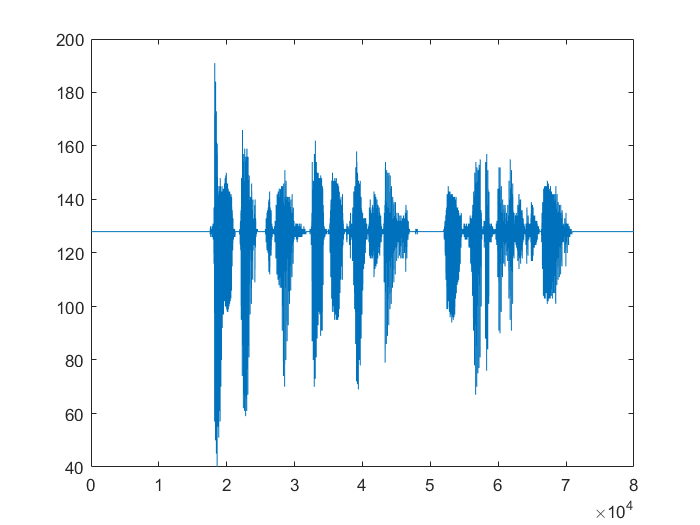

recordblocking(rec,5);
audioData = getaudiodata(rec,'uint8')';
plot(audioData);

## Call Python speech recognizer and convert outputs to MATLAB data types

pyOut = py.mySpeechRecognizer.audioToText(audioData,sampleRate,numChannels);
myText = string(pyOut{1});
successFlag = logical(pyOut{2});
disp(myText)

i'm on my favorite restaurant and have a delicious meal


## Perform sentiment analysis

NOTE: If you are in a version older than R2019b, you can instead use the `sentimentAnalysisCustom` function.

[sentiment,scores] = sentimentAnalysisVADER(myText)

sentiment = 'Positive'

scores = 1×3 single row vector
         0    0.5109    0.4891


*Copyright 2019 - 2022 The MathWorks, Inc.*